# Exploring continuous data with gramm

In this example file, we will go further in exploring gramm's capabilities for data where some independent variables are continuous data.

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, we have four different subjects (`subject`), each coming for two sessions (`session`) on consecutive days at the lab. During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference direction`) in a circle around a starting point. The cursor is difficult to control, and as a marker for progress, we record whether they reach the target in time (`hit`), how long was their reaction time (`m_reaction_time`), their movement (`m_movement_duration`), and what was the distance covered by the cursor (`m_dist`). Each line corresponds to a trial (`trial_index`), and we transformed the index in percentage of time elapsed within session (`valid_perc`) or across sessions (`valid_perc_session`)

## Simple visualization of raw datapoints

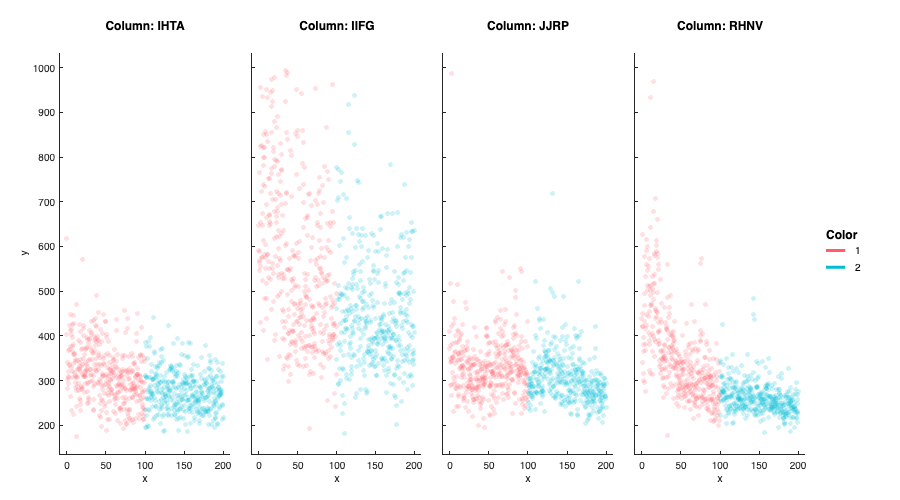

figure('Position',[100 100 900 500])
g=gramm('x',T.valid_perc_session,'y',T.m_reaction_time,'color',T.session);
g.facet_grid([],T.subject,'scale','free_y');
g.geom_point('alpha',0.2);
%g.stat_summary('bin_in',10);
%g.stat_smooth('method','smoothingspline','lambda',0.00001);
%g.stat_fit('fun',@(b,x)b(3)+b(1).*exp(x.*b(2)),'StartPoint',[1000 -0.01 150],'stats',true,'intopt','functional','ErrorModel','combined');
%g.stat_fit('fun',@(a,b,c,x)c+a.*exp(x.*b),'StartPoint',[1000 -0.01 150],'intopt','functional');
%g.stat_glm();
%g.axe_property('YLim',[50 600]);
g.draw();